# **Discrete Optimal Path Demo:**

## Problem Formulation:

This script shows how we can find the shortest path from a start goal to an end goal through a field of obstacles.  We will solve for the optimal path using the following minimization:


$$  \begin{array}{ccc}
    \underset{\mathbf{x},\mathbf{y}}\text{min} & \sum_{i=1}^N\sqrt{(x_i-x_{i-1})^2 + (y_i-y_{i-1})^2} &  \\
    s.t. & (x_j - x_c)^2 + (y_j - y_c)^2 > R_c^2, &\forall j \in \{1,\ldots, N-1\} \\
    & (x_0,y_0) = (x_{start},y_{start}) \\
 & (x_N,y_N) = (x_{end},y_{end})
  \end{array}$$


This problem formulation minimizes the distance between a point and its neighbors along a discrete trajectory.  The first constraint enforces that the solution cannot intersect the obstacles.  It does this by checking if the point, (x_j,y_j), is not within the radius of the obstacle, R_c.  The second and third contstraint specify that the start and end points are fixed based on our desired start and end coordinates.  This demo shows how this solution can be implemented.

% preliminaries
clearvars
clf()
% global vars needed to get data from fmincon
global outputFcn_global_data x_vals obstacles 

## One Obstacle Implementation:

The first step is to setup out course load an obstacle course.  There are some already provided in ./obstacle_envs.  We will also choose our start and end points.

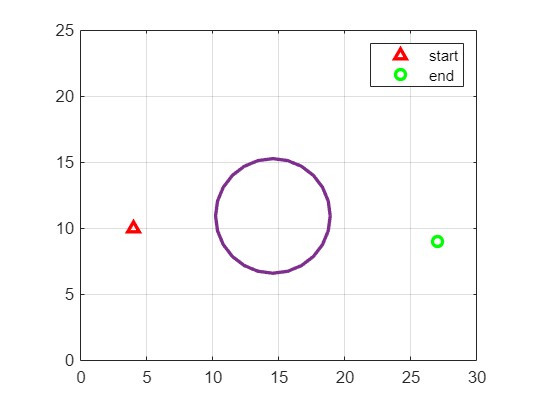

obstacles = read_obstacle_file('obstacle_envs/1_obstacle.txt'); % if obstacle file is changed, guess needs to be changed as well
figure(1)
x0 = 4; y0 = 10; xf = 27; yf = 9;
x_start = [x0,y0]; x_end = [xf,yf];
plot_env(x_start,x_end,obstacles)
make_legend('start','end','')

To find the optimal path from the start to end goal, we can take a guess at the optimal solution, and then use constrained optimization to find our best solution.  For now we will load an initial guess.  We will use a guess that goes around the bottom of this obstacle.  New initial guesses can be created with short_dist_multi_obs.m and saved to demo_guess.mat.

These guesses were made with dx = 0.5 between points on the discrete trajectory.

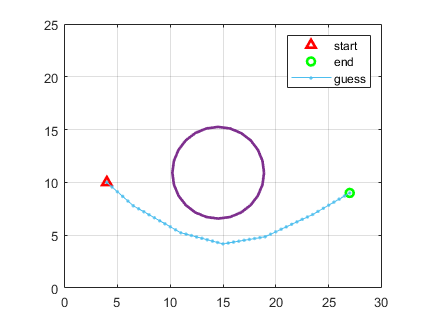

load('demo_guess.mat')
x_span = x_one_obs; 
y_span_guess = y_one_obs_0; % guess below or above can be selected
figure(2)
plot_env(x_start,x_end,obstacles)
plot_guess(x_span,y_span_guess)
make_legend('start','end','','guess')

With our guess and environment established, we are now ready to set up our minimization problem.  First we build our objective function, f, as the euclidean distance between each pair of points.  Our distance between x coordinates is a constant, dx, specified when making the guesses.


$$\sum_{i=1}^N\sqrt{(x_i-x_{i-1})^2 + (y_i-y_{i-1})^2}
$$


% build objective function
f = @(y)  sqrt(dx^2 + (y(1)-y0)^2);
for ii = 1:N-2
    f = @(y) f(y) + sqrt(dx^2 + (y(ii+1)-y(ii))^2);
end
f = @(y) f(y) + sqrt(dx^2 + (yf - y(N-1))^2);

Next we set up the constrained minimization problem using fmincon.  The function obst_constraints, implements the constraint preventing our solution from intersecting with the obstacle, i.e.


$$  \begin{array}{cc}
 (x_j - x_c)^2 + (y_j - y_c)^2 > R_c^2, &\forall j \in \{1,\ldots, N-1\} \\

  \end{array}$$


options = optimoptions(@fmincon,'MaxIterations',4e4,'MaxFunctionEvaluations',8.2e5,'OutputFcn',@outputFcn_global,'OptimalityTolerance',1e-8);
x_vals = x_span; % used by constraints function
y_guess = y_span_guess(2:end-1); % exclude the end points from our initial guess as those points are fixed
A = []; b = []; Aeq = []; beq = []; lb = []; ub = [];
[x,fval,exitflag,output] = fmincon(f,y_guess,A,b,Aeq,beq,lb,ub,@obst_constraints,options)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     9.8255    9.6509    9.4764    9.3019    9.1273    8.9528    8.7782    8.6037    8.4292    8.2546    8.0801    7.9056    7.7310    7.5565    7.3820    7.2074    7.0329    6.8583    6.7016    6.6082    6.5739    6.5975    6.6798    6.7807    6.8815    6.9824    7.0833    7.1842    7.2851    7.3859    7.4868    7.5877    7.6886    7.7894    7.8903    7.9912    8.0921    8.1930    8.2938    8.3947    8.4956    8.5965    8.6974    8.7982    8.8991


fval = 23.8054

exitflag = 2

output = struct with fields:
         iterations: 79
          funcCount: 3678
    constrviolation: 0
           stepsize: 1.8436e-09
          algorithm: 'interior-point'
      firstorderopt: 2.7717e-07
       cgiterations: 117
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


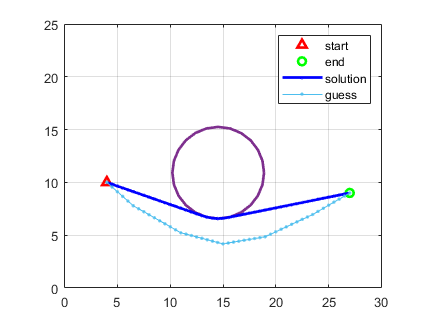

opt_results = outputFcn_global_data;

% plot results
figure(3)
y_out = [y0 x yf];
x_out = x_span;
plot_env(x_start,x_end,obstacles)
plot_solution(x_out,y_out)
plot_guess(x_out,y_span_guess)
make_legend('start','end','','solution','guess')

If "guess_below" is selected for our guess, the minimization solution iterations can be seen below.

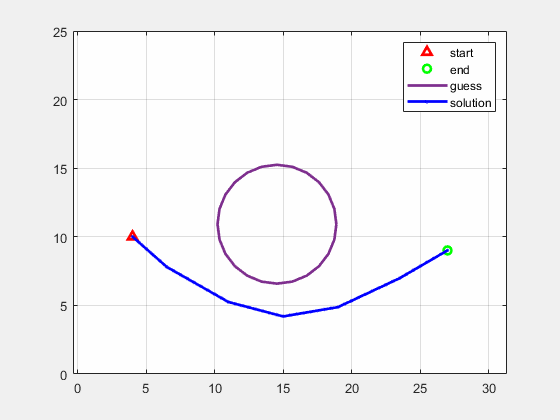

If "guess_above" is selected, the gif results are shown here:

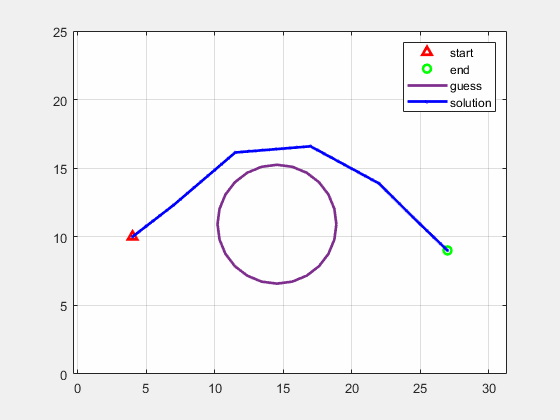

As you can see from these results, the quality of our solution is dependent on our initial guess.  This means our problem formulation will only result in a locally optimal solution.

For further investigation, try running the script short_dist_multi_obs.m.  This script provides an interface for easily making initial guesses for our optimizer.  The code used for this is available at [https://github.com/rpalfini/discrete_path_find.git](https://github.com/rpalfini/discrete_path_find.git)